% 参数设置
N = 64; K = 37;
% N = 225; K = 128;
L = 1; % 计算区域边界
R = 0.13; % 点的最小间距
M = 0;
D = 0;
alpha = 0;
K_ = 2*pi/L * sqrt(K);
f = 2;

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     129    1.531857e+05    0.000e+00    7.178e+04
    1     258    1.486120e+05    4.165e-02    8.164e+04    1.691e-01
    2     387    1.408292e+05    3.977e-02    6.324e+04    1.784e-01
    3     516    1.389750e+05    4.074e-02    6.406e+04    2.031e-02
    4     645    1.280710e+05    2.258e-02    6.754e+04    2.303e-01
    5     774    1.255146e+05    2.694e-02    6.383e+04    2.871e-02
    6     903    7.219419e+04    2.649e-02    3.596e+04    2.602e-01
    7    1032    7.153831e+04    2.647e-02    4.092e+04    2.649e-01
    8    1161    6.755494e+04    2.645e-02    3.316e+04    1.288e-01
    9    1290    6.629222e+04    2.636e-02    4.630e+04    2.884e-01
   10    1419    6.558473e+04    2.635e-02    4.298e+04    2.684e-02
   11    1548    6.215033e+04    2.629e-02    3.823e+04    1.605e-01
   12    1677    6.124437e+04    2.628e-02    3

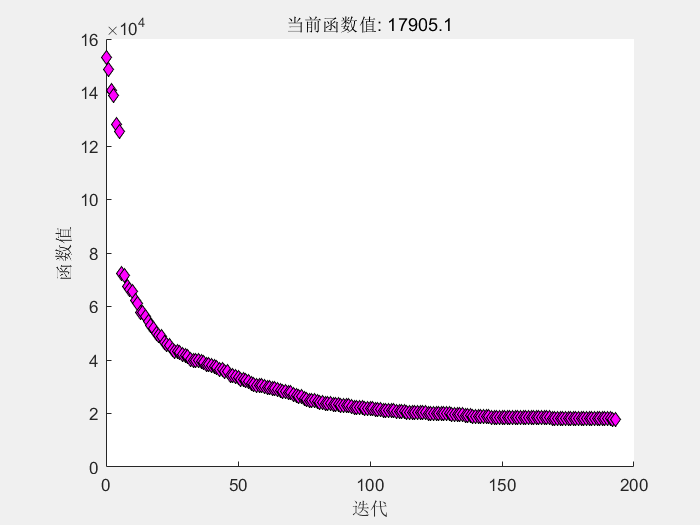


fmincon stopped by the output or plot function.




% 生成 Hyperuniform 点分布
% K是截止波数的平方
start_points = hyperuniform_points;
% start_points = generate_random_points_in_circle(N, L);
hyperuniform_points = generate_hyperuniform_points(start_points, N, L, K, R, D, alpha, f);

hyperuniform_points = reshape(hyperuniform_points, N, 2);

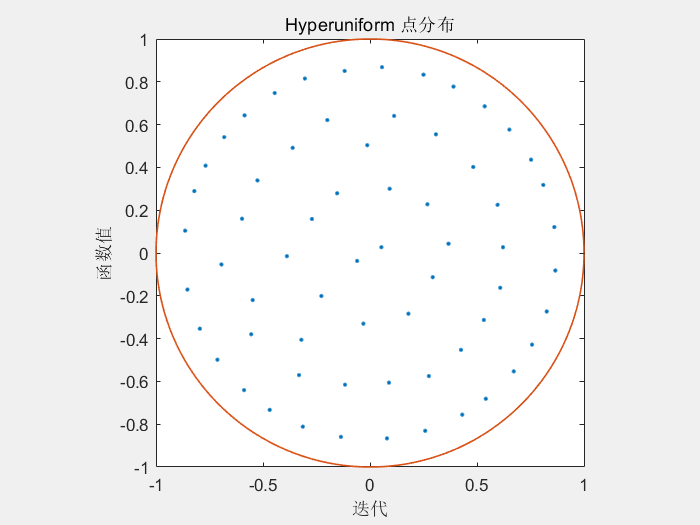

% 绘制点分布
figure (1);
p = scatter(hyperuniform_points(:, 1), hyperuniform_points(:, 2), 50, '.');
axis equal;  
xlim([-L, L]);
ylim([-L, L]);
title('Hyperuniform 点分布'); 
box on;
% 叠加截止区域圆（K）
hold on;
theta = 0:0.01:2*pi;
x_circle = L * cos(theta);
y_circle = L * sin(theta);
plot(x_circle, y_circle, 'LineWidth', 1);
hold off;

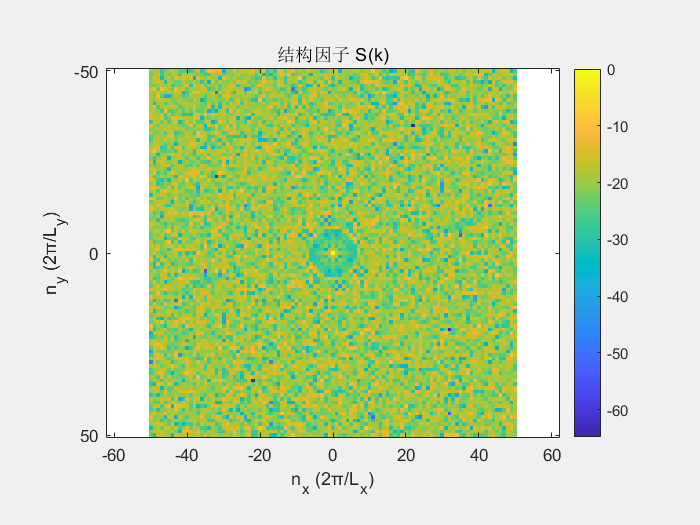


% 定义倒空间波矢范围
k_max = 50;         % 最大波矢值（单位：2π/L）
k_resolution = 101; % 分辨率
[kx, ky] = meshgrid(linspace(-k_max, k_max, k_resolution), ...
                    linspace(-k_max, k_max, k_resolution));

% 计算结构因子 S(k)
S = zeros(size(kx));
Mk = 0;
for i = 1:numel(kx)
    k = 2 * pi * [kx(i)/f*L, ky(i)/f*L];  % 波矢定义（实际物理单位）
    if kx(i) ^2 + ky(i) ^2 <= K
        Mk = Mk+1;
    end
    sum_exp = 0;
    for j = 1:N
        sum_exp = sum_exp + exp(1j * dot(k, hyperuniform_points(j, :)));
    end
    S(i) = abs(sum_exp)^2 / N;
end

Mk = (Mk-1)/2;
chi = Mk /2 /N;
norm_S = 10 * log10(S / max(S(:)));
% 绘制结构因子
figure (2);
imagesc(kx(1,:), ky(:,1), norm_S);
axis equal;
xlabel('n_x (2π/L_x)');
ylabel('n_y (2π/L_y)');
title('结构因子 S(k)');
colorbar;

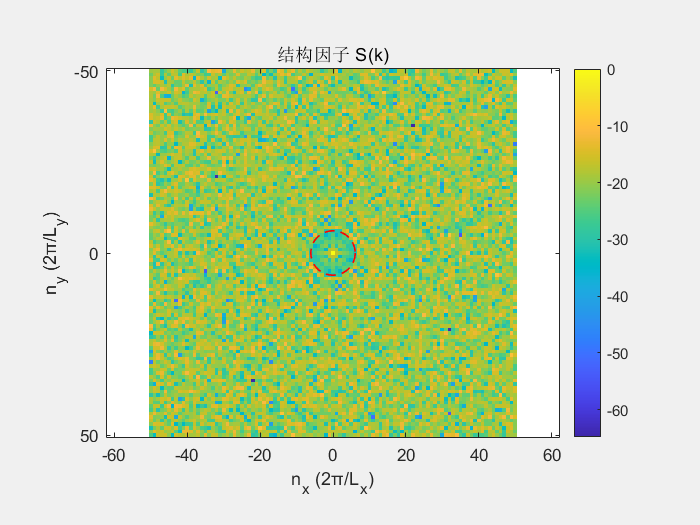

% 叠加截止区域圆（K）
hold on;
theta = 0:0.01:2*pi;
x_circle = sqrt(K) * cos(theta);
y_circle = sqrt(K) * sin(theta);
plot(x_circle, y_circle, 'r--', 'LineWidth', 1);
hold off;

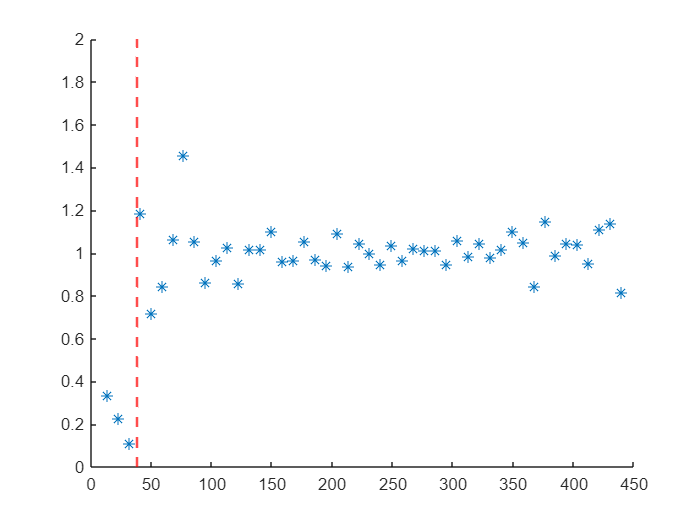

% 计算波矢模长 |k|
norm_k = 2 * pi / L * sqrt(kx.^2 + ky.^2);  % 注意！单位：2π/L
norm_k_flat = norm_k(:);        % 展平为一维数组
S_flat = S(:);                  % 展平为一维数组

% 定义模长平均的范围
bin_edges = linspace(0, max(norm_k_flat), 50);  % 100 个 bins
bin_centers = (bin_edges(1:end-1) + bin_edges(2:end)) / 2;

% 将 S(k) 按 |k| 分组并计算平均值
S_mean = zeros(1, length(bin_centers));
for i = 1:length(bin_edges)-1
    mask = (norm_k_flat >= bin_edges(i)) & (norm_k_flat < bin_edges(i+1));
    S_mean(i) = mean(S_flat(mask));
end

% 绘制 S(k) 随 |k| 的变化曲线
figure;
scatter(bin_centers, S_mean, 50, '*'); 
xline(K_, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Cutoff K');
ylim([0, 2]);

function hyperuniform_points = generate_hyperuniform_points(start_points, N, L, K, R, D, alpha, f)
    % 生成 Hyperuniform 点分布
    % 输入参数：
    %   N: 点的数量
    %   Lx, Ly: 计算区域的边长
    %   K: 倒空间截止波数
    %   R: 点的最小间距（硬球半径）
    % 输出：
    %   hyperuniform_points: N x 2 矩阵，表示点的坐标

    % 初始化随机点分布
    points = start_points;

    % 定义优化目标函数
    objective = @(x) total_potential_energy(x, N, L, K, D, alpha, f);

    % 定义约束条件
    nonlcon = @(x) constraints(x, N, R, L);

    % 示例：使用遗传算法
%     options_ga = optimoptions('ga', 'PopulationSize', 100, 'MaxGenerations', 100, 'Display','iter', 'UseParallel', true);
%     optimized_points = ga(objective, 2*N, [], [], [], [], zeros(2*N, 1), ones(2*N, 1), nonlcon, options_ga);

%     优化选项
    options = optimoptions('fmincon', 'Algorithm', 'interior-point', ...
                           'Display', 'iter', 'MaxIterations', 200, 'MaxFunctionEvaluations', 500 * N , 'PlotFcn','optimplotfval');

%     调用 fmincon 进行优化
    optimized_points = fmincon(objective, points, [], [], [], [], ...
                               -L .* ones(N, 2), L .* ones(N, 2), ...
                               nonlcon, options);

    % 返回优化后的点分布
    hyperuniform_points = optimized_points;
end

function phi = total_potential_energy(points, N, L, K, D, alpha, f) 
    % 计算总势能
    phi = 0;
    M = 0;
    points = reshape(points, N, 2); % 将向量转换为 N x 2 矩阵
    
    % 遍历所有波矢 k
    for nx = -50:50
        for ny = -50:50
            k = 2 * pi * [nx/f*L, ny/f*L]; % 波矢
            if nx ^2 + ny^2 <= K && nx ^2 + ny^2 ~= 0 % k在K内，相当于辅助函数
                C0 = -N/2 + D * norm(k) ^ alpha;
                M = M + 1;
                Ck = 0;
                for j = 1:N-1
                    for l = j+1:N
                        Ck = Ck + cos(dot(k, points(j, :) - points(l, :)));
                    end
                end
                phi = phi + (C0 - Ck) ^2;
            end
        end
    end
    M = (M-1) / 2;
end

function [c, ceq] = constraints(points, N, R, L)
    % 定义约束条件
    points = reshape(points, N, 2); % 将向量转换为 N x 2 矩阵
    c = []; % 不等式约束
    ceq = []; % 等式约束

    % 最小间距约束
    for j = 1:N-1
        for l = j+1:N
            dist = norm(points(j, :) - points(l, :));
            c = [c; R - dist]; % 确保 dist >= R
        end
    end

    % 边界约束（点必须在计算区域内）
    for j = 1:N
        c = [c; norm(points(j,:)) - L + R];
    end
end

function points = generate_random_points_in_circle(N, radius)
    % N: 需要生成的随机点的数量
    % radius: 圆的半径

    % 生成随机角度 (0 到 2*pi)
    theta = 2 * pi * rand(N, 1);

    % 生成随机半径 (0 到 radius)，注意要进行平方根变换以确保均匀分布
    r = sqrt(rand(N, 1)) * radius;

    % 将极坐标转换为笛卡尔坐标
    x = r .* cos(theta);
    y = r .* sin(theta);

    % 组合成 N x 2 的数组
    points = [x, y];
end